clear;clc;

% load clock parameters
par_clock = load('par_clock.csv');

y0 = zeros(12, 1);
tmax = 1000;
tspan = 0:1:tmax;

% y1: normal clock
[~, y1] = ode15s(@ODE_Clock, tspan, y0, [], par_clock);

% y2: Smaller amplitude
vmax_bmal = par_clock(17);
par_clock(17) = 0.2;
[~, y2] = ode15s(@ODE_Clock, tspan, y0, [], par_clock);
par_clock(17) = vmax_bmal;

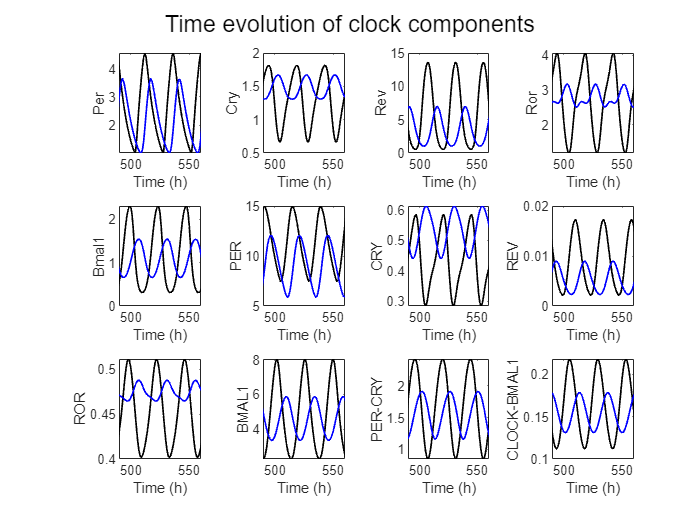

clock_name = ["Per", "Cry", "Rev", "Ror", "Bmal1", "PER", "CRY", "REV", "ROR", "BMAL1", "PER-CRY", "CLOCK-BMAL1"];
figure;
for i = 1:12
    subplot(3, 4, i);
    plot(tspan, y1(:, i), 'k', 'LineWidth', 1); hold on;
    plot(tspan, y2(:, i), 'b', 'LineWidth', 1); hold on;
    xlim([490 560]);
%     xlim([446 494]);
%     yl = ylim;
%     patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
%     ylim(yl);
    xlabel('Time (h)');
    ylabel(clock_name(i));
end
sgtitle('Time evolution of clock components');
hold off;

figure;
subplot(2,2,1);
plot(tspan, y1(:, 5), 'LineWidth', 1); xlim([490 560]);
xlabel('t (h)'); ylabel('Bmal1'); title('Pertubation time: 505');
subplot(2,2,2);
plot(tspan, y2(:, 5), 'LineWidth', 1); xlim([490 560]);
xlabel('t (h)'); ylabel('Bmal1'); title('Pertubation time: 511');
subplot(2,2,3);
plot(tspan, y3(:, 5), 'LineWidth', 1); xlim([490 560]);
xlabel('t (h)'); ylabel('Bmal1'); title('Pertubation time: 517');
subplot(2,2,4);
plot(tspan, y4(:, 5), 'LineWidth', 1); xlim([490 560]);
xlabel('t (h)'); ylabel('Bmal1'); title('Pertubation time: 523');